# Track and Label Bounding Box(Cuboid) Automatically Based on predefined Bounding Box

Deep Learning is really powerful approach to classify objects from point cloud. Good ground truth data is crucial for training deep neural network for classification. However, creating and maintaining a diverse and high-quality set of annotated data requires significant effort. The groundTruthLabeler and makes this process easy and efficient and this semi-automation algorithm can be used with groundTruthLabeler to help you to label cuboids. This automatetion algorithms uses automatic clustering and tracking algorithms which create labels for all frames automatically based on labels manually defined for just first frame.

-- [Japanese]

Deep Learningの登場により点群データからの物体分類等が高い精度で実現できるようになってきました。一方、点群データを処理するためのネットワークを学習させるためには膨大な量のデータが必要であり、Bounding Box(Cuboid)ラベルが付けられたデータを準備する作業は非常に多くの時間・リソースを必要とします。Ground Truth Labelerによりこれらの作業を効率化することができますが、カスタムの半自動化アルゴリズムを追加することも可能で、目的に応じて様々なアルゴリズムを選択できます。本ファイルはGround Truth Labelerと組み合わせて利用できる半自動化アルゴリズムの一つです。自動クラスタリングとトラッキングのアルゴリズムを利用し、ユーザーが最初のフレームに対して付与したラベルをベースに、残りの全てのフレームに対してラベルが自動付与されます。

clear all, close all, clc;

## Prepare Point Cloud Data

[Japanese] ラベリングの対象となる点群データを準備します。

load('lidarData_2.mat')
mkdir lidarSeq
for i = 1:length(currentLidarData)
    tmp = currentLidarData{i};
    fname = ['lidarSeq/ptcloud_', sprintf('%03d', i), '.pcd'];
    pcwrite(tmp, fname)
    if i > 36
        break
    end
end

## Visualize Prepared Data

[Japanese] データを確認します。

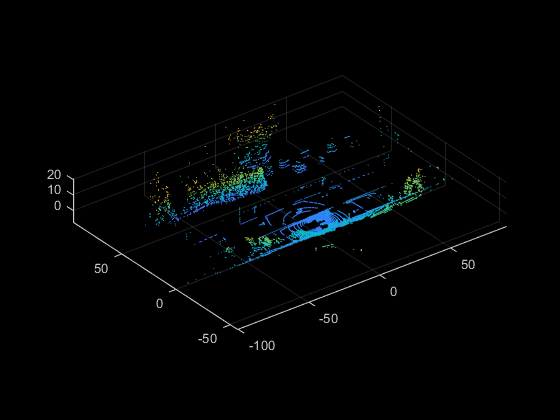

ptCloud = pcread('lidarSeq/ptcloud_001.pcd');
pcshow(ptCloud)

## Create Ground Truth Label Data

[Japanese] Ground Truthオブジェクトを準備します。

ldc = labelDefinitionCreatorMultisignal;
addLabel(ldc,'Vehicle','Rectangle');
labelDefs = create(ldc)

labelDefs = 2×6 table
       Name        SignalType    LabelType     Group      Description    LabelColor
    ___________    __________    _________    ________    ___________    __________

    {'Vehicle'}    Image         Rectangle    {'None'}       {' '}       {0×0 char}
    {'Vehicle'}    PointCloud    Cuboid       {'None'}       {' '}       {0×0 char}



sourceDir = fullfile(pwd, 'lidarSeq');
pcseqSource = vision.labeler.loading.PointCloudSequenceSource;
pcseqSource.loadSource(sourceDir,[]);

numPCFrames = numel(pcseqSource.Timestamp{1});
carData = cell(numPCFrames, 1);
tmp = cell(2,1);
tmp{1} = [10.6682 3.5468 0.7811 4.4641 1.6022 1.1086 0 0 0];
tmp{2} = [0.9517 -3.7368 0.8080 3.7986 1.5299 0.6064 0 0 0];
carData{1} = tmp;
lidarData = timetable(pcseqSource.Timestamp{1},carData,'VariableNames',{'Vehicle'});
roiData = vision.labeler.labeldata.ROILabelData('lidarSeq',{lidarData});

sceneData = vision.labeler.labeldata.SceneLabelData.empty;
gTruth = groundTruthMultisignal(pcseqSource, labelDefs, roiData, sceneData)

gTruth =   groundTruthMultisignal with properties:

          DataSource: [1×1 vision.labeler.loading.PointCloudSequenceSource]
    LabelDefinitions: [2×6 table]
        ROILabelData: [1×1 vision.labeler.labeldata.ROILabelData]
      SceneLabelData: [0×0 vision.labeler.labeldata.SceneLabelData]


## Launch Ground Truth Labeler

[Japanese] Ground Truth Labelerを起動します。

groundTruthLabeler

## Import gTruth

[Japanese] 予め順具しておいたGround Truthオブジェクトを読み込みます。

Step 1 : On the app toolstrip, on the Label tab, click "Open" and select "Import Labels" (From Workspace) 

[Japanese] LabelerのツールストリップでLabelタブをクリックし、"Open" > "Import Labels" > "From Workspace"の順に選択します。

Step 2 : Select gTruth variable in the dialog box that opens.

You will see the point cloud data and labeled objects on the labeler like this;

[Japanese] ダイアログボックス上でワークスペースにあるgTruth変数を選択します。Labelerに点群データとラベル情報がロードされます。

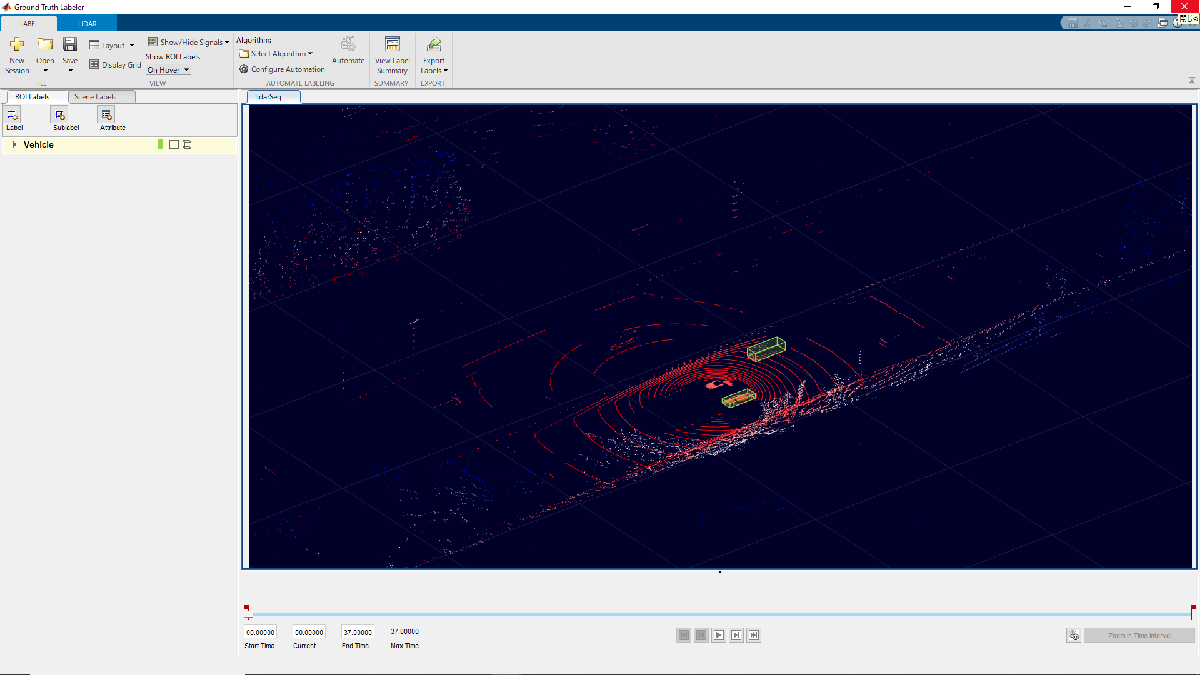

## Add Automation Algorithm into the Ground Truth Labeler and Use it

[Japanese] 半自動化のアルゴリズムをGround Truth Labelerに追加し、利用します。

Step 1 : On the app toolstrip, on the Label tab, click "Select Algorithm" > "Add Algorithm" > "Import Algorithm".

[Japanese] Labelerのツールストリップ上にあるLabelerタブを選択、"Select Algorithm" > "Add Algorithm" > "Import Algorithm"の順に選択します。

Step 2 :  Select BoundingBoxTracker.m in the explorer that opens.

[Japanese] 起動したエクスプローラー上でBoundingBoxTracker.mを選択します。

Step 3 : Click "Select Algorithm" > "Bounding Box(Cuboid) Tracker" and then Click "Automate".

[Japanese] "Select Algorithm" > "Bounding Box(Cuboid) Tracker"の順に選択し、"Automate"を押します。

Step 4 : Preprocess for point cloud : Snap to Clusters. This labeler provides an option to snap clasters from point cloud by using some segmentation algorithms such as pcdist. On the app toolstrip, on the Lidar tab, click "Snap to Cluster".

[Japanese] 点群データに対し前処理を施します(クラスタリング)。Labelerにはクラスタリングのためのオプションが備わっており、pcdist等幾つかのアルゴリズムを選択してクラスタリングを行えます。Labelerのツールストリップ上にあるLidarタブを選択、"Snap to Cluster"をクリックします。

Step 5 : Preprocess for point cloud : Hide Ground. The point cloud data includes points from the ground in many cases which can make it more difficult to isolate the object you want to label. On the app toolstrip, on the Lidar tab, click "Hide Ground".

[Japanese] 点群データに対し前処理を施します(地表面の除去)。多くの点群データには地表面が含まれますが、対象オブジェクトをラベリングする際に不要なデータとなるため、予め除去しておきます。Labelerのツールストリップ上にあるLidarタブを選択、"Hide Ground"をクリックします。

Step 6 : Label Cuboid for first frame manually. In the ROI Labels pane on the left click the label you want to automate, and move the pointer over the object you want to label until the gray preview cuboid encloses the object points. And then click the signal frame to draw the cuboid. In this example, label cuboids for two cars like this;

[Japanese] 最初のフレームに対しては手動でラベリングを行います。Labeler左部にあるROIラベルから自動化したいラベルを選択し、その後にマウスカーソルを対象オブジェクトまで移動させます。対象のオブジェクトが灰色のCuboidで囲まれたら、左クリックしてラベルを確定させます。この例題では、以下のように2つの自動車の点群に対してラベルを付与します。

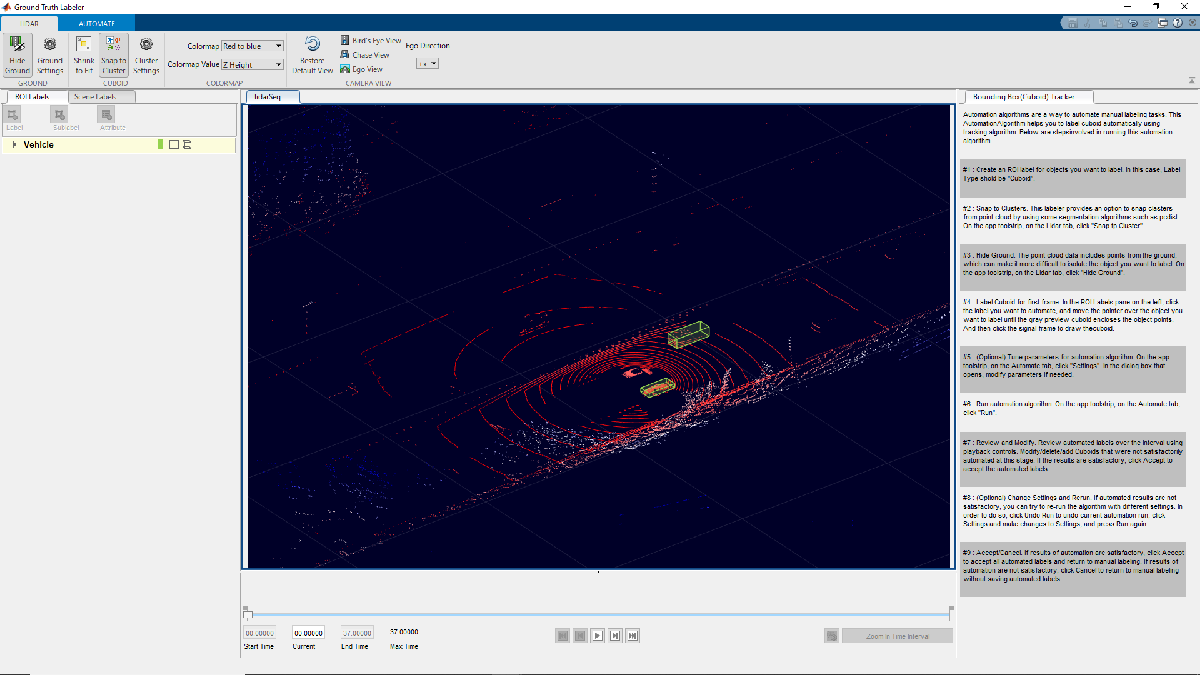

Step 7 : Run automation algorithm. On the app toolstrip, on the Automate tab, click "Run. You will see the automatically labeled cuboids in every frames. If the results are satisfactory, click Accept to accept the automated labels.

[Japanese] 半自動化アルゴリズムを実行します。Labelerのツールストリップ上にあるAutomateタブを選択、"Run"をクリックします。最初に手動で付与したラベルをベースとしてトラッキングのアルゴリズムが実行され、すべてのフレームに対してラベルが自動付与されます。所望の結果が得られていれば"Accept"を押して自動化を終了します。

Copyright 2020 The MathWorks, Inc.